# Chapter 2 Exercise Solutions

## Exercise 2.1


$$\begin{array}{c|cccc}
    0 & 0 \\
    \frac{1}{4} & \frac{1}{4} \\
    \frac{1}{2} & 0 & \frac{1}{2} \\
    1 & 1 & -2 & 2 \\ \hline
    & \frac{1}{6} & 0 & \frac{2}{3} & \frac{1}{6}
\end{array}$$


## Exercise 2.2


$$\begin{array}{rl}
y_{n+1} &= y_n + \frac{h}{9} (4k_2 + 3k_3 + 2k_4), \\
k_1 &= f(t_n, y_n), \\
k_2 &= f(t_n + \frac{1}{4}h, y_n + \frac{1}{4}h k_1), \\
k_3 &= f(t_n + \frac{1}{2}h, y_n + h(-\frac{1}{2}k_1 + k_2)), \\
k_4 &= f(t_n + h, y_n + h(\frac{1}{4}k_1 + \frac{3}{4}k_3)).
\end{array}$$


## Exercise 2.3

syms a21 b1 b2 c2
b1 = 1/3;

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = b2 * c2 == 1/2;
eq3 = a21 == c2;

% Solve order conditions
solve(eq1, eq2, eq3)

ans = struct with fields:
    a21: 3/4
     b2: 2/3
     c2: 3/4


## Exercise 2.4


$$\begin{array}{rl}
    r(\tau) &= 10, \\
    \Phi(\tau) &= \sum_{i,j,k,\ell} b_i a_{ij} a_{ik} a_{k\ell} c_j^3 c_k c_\ell^2, \\
    \gamma(\tau) &= 600.
\end{array}$$


## Exercise 2.5

Using $\Phi(\tau) = \frac{1}{\gamma(\tau)}$ then


$$\begin{array}{rl}
\sum_{i=1}^3 b_i &= 1, \\
  \sum_{i=1}^3 b_ic_i &= \frac{1}{2}, \\
  \sum_{i=1}^3 b_ic_i^2 &= \frac{1}{3}, \\
  \sum_{i,j=1}^3 b_ia_{ij}c_j &= \frac{1}{6}, \\
\end{array}$$


Since $c_1 = 0$ and $a_{ij} = 0$ where $i \leq j$ then the order conditions are


$$\begin{array}{rl}
    b_1 + b_2 + b_3 &= 1, \\
    b_2c_2 + b_3c_3 &= \frac{1}{2}, \\
    b_2c_2^2 + b_3c_3^2 &= \frac{1}{3}, \\
    b_3a_{32}c_2 &= \frac{1}{6}, \\
    a_{21} &= c_2, \\
    a_{31} + a_{32} &= c_3
\end{array}$$


## Exercise 2.6

% Declare symbolic variables
syms a21 a31 a32 a41 a42 a43 b1 b2 b3 b4
c2 = 1/3;
c3 = 1/2;
c4 = 1;

% Define order conditions
eq1 = b1 + b2 + b3 + b4 == 1;
eq2 = b2 * c2 + b3 * c3 + b4 * c4 == 1/2;
eq3 = b2 * c2^2 + b3 * c3^2 + b4 * c4^2 == 1/3;
eq4 = b2 * c2^3 + b3 * c3^3 + b4 * c4^3 == 1/4;
eq5 = b3 * a32 * c2 + b4 * a42 * c2 + b4 * a43 * c3 == 1/6;
eq6 = b3 * a32 * c2 * c3 + b4 * a42 * c2 * c4 + b4 * a43 * c3 * c4== 1/8;
eq7 = b3 * a32 * c2^2 + b4 * a42 * c2^2 + b4 * a43 * c3^2 == 1/12;
eq8 = b4 * a43 * a32 * c2 == 1/24;
eq9 = c2 == a21;
eq10 = c3 == a31 + a32;
eq11 = c4 == a41 + a42 + a43;

% Solve order conditions
solve(eq1, eq2, eq3, eq4, eq5, eq6, eq7, eq8, eq9, eq10, eq11)

ans = struct with fields:
    a21: 1/3
    a31: 1/8
    a32: 3/8
    a41: 1/2
    a42: -3/2
    a43: 2
     b1: 1/6
     b2: 0
     b3: 2/3
     b4: 1/6



$$\begin{array}{c|cccc}
    0 & 0 \\
    \frac{1}{3} & \frac{1}{3} \\
    \frac{1}{2} & \frac{1}{8} & \frac{3}{8} \\
    1 & \frac{1}{2} & -\frac{3}{2} & 2 \\ \hline
    & \frac{1}{6} & 0 & \frac{2}{3} & \frac{1}{6} 
\end{array}$$


## Exercise 2.7


$$\begin{array}{rl}
    y_0 &= 1, \\ 
    t_0 &= 0, \\ \\ 
    k_1 &= 0.0 - 1.0000 = -1.0000, \\ 
    k_2 &= (0.0 + \frac{3}{4}(0.4)) - (1.0000 + \frac{3}{4}(0.4)(-1.0000)) = -0.4000, \\ 
    y_1 &= 1.0000 + \frac{1}{3}(0.4)(-1.0000 + 2(-0.4000)) = 0.7600,\\  
    t_1 &= 0.0 + 0.4 = 0.4, \\ \\ 
    k_1 &= 0.4 - 0.7600 = -0.3600, \\ 
    k_2 &= (0.4 + \frac{3}{4}(0.4)) - (0.7600 + \frac{3}{4}(0.4)(-0.3600)) = 0.0480, \\ 
    y_2 &= 0.7600 + \frac{1}{3}(0.4)(-0.3600 + 2(0.0480)) = 0.7248,\\  
    t_2 &= 0.4 + 0.4 = 0.8, \\ \\ 
    k_1 &= 0.8 - 0.7248 = 0.0752, \\ 
    k_2 &= (0.8 + \frac{3}{4}(0.4)) - (0.7248 + \frac{3}{4}(0.4)(0.0752)) = 0.3526, \\ 
    y_3 &= 0.7248 + \frac{1}{3}(0.4)(0.0752 + 2(0.3526)) = 0.8289,\\  
    t_3 &= 0.8 + 0.4 = 1.2, \\ \\ 
    k_1 &= 1.2 - 0.8289 = 0.3711, \\ 
    k_2 &= (1.2 + \frac{3}{4}(0.4)) - (0.8289 + \frac{3}{4}(0.4)(0.3711)) = 0.5598, \\ 
    y_4 &= 0.8289 + \frac{1}{3}(0.4)(0.3711 + 2(0.5598)) = 1.0276,\\  
    t_4 &= 1.2 + 0.4 = 1.6, \\ \\ 
    k_1 &= 1.6 - 1.0276 = 0.5724, \\ 
    k_2 &= (1.6 + \frac{3}{4}(0.4)) - (1.0276 + \frac{3}{4}(0.4)(0.5724)) = 0.7007, \\ 
    y_5 &= 1.0276 + \frac{1}{3}(0.4)(0.5724 + 2(0.7007)) = 1.2908,\\  
    t_5 &= 1.6 + 0.4 = 2.0, \\ \\ 
\end{array}$$


## Exercise 2.8

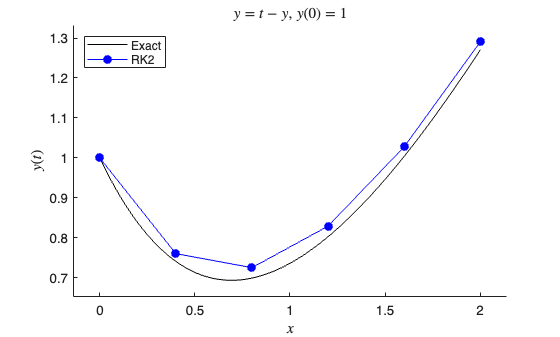

% Define RK2 function
function [t, y] = rk2(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
m = length(y0);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, m);
t(1) = tspan(1);
y(1,:) = y0;

for n = 1 : length(t) - 1
    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + 3/4 * h, y(n,:) + 3/4 * h * k1);
    y(n+1,:) = y(n,:) + h / 3 * (k1 + 2 * k2);
    t(n+1) = t(n) + h;
end

end

% Define ODE function
f = @(t, y) t - y;

% Define IVP parameters
tspan = [0, 2]; % boundaries of the t domain
y0 = 1;         % initial values
h = 0.4;        % step length

% Solve IVP
[t, y] = rk2(f, tspan, y0, h);

% Calculate exact solution
exact = @(t) t + 2 * exp(-t) - 1;
texact = linspace(tspan(1), tspan(2), 100);
yexact = exact(texact);

% Plot solution
clf
hold on
plot(texact, yexact, 'k');
plot(t, y, 'b-o', MarkerFaceColor='b');
hold off
xlabel('$x$', Interpreter='latex')
ylabel('$y(t)$', Interpreter='latex')
title('$y = t - y$, $y(0) = 1$', Interpreter='latex')
legend('Exact', 'RK2', Location='NorthWest')
axis padded

## Exercise 2.9

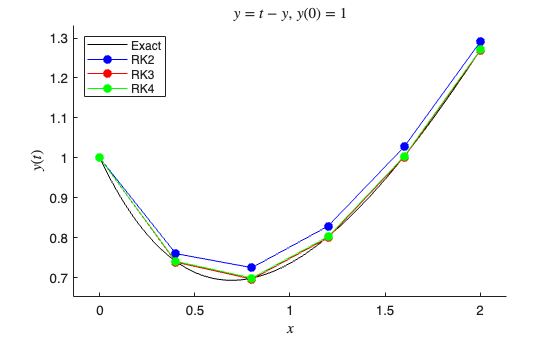

% Define RK3 function
function [t, y] = rk3(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
m = length(y0);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, m);
t(1) = tspan(1);
y(1,:) = y0;

for n = 1 : length(t) - 1
    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + 1/2 * h, y(n,:) + 1/2 * h * k1);
    k3 = f(t(n) + h, y(n,:) + h * (-k1 + 2 * k2));
    y(n+1,:) = y(n,:) + h / 6 * (k1 + 4 * k2 + k3);
    t(n+1) = t(n) + h;
end

end

% Define RK4 function
function [t, y] = rk4(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
m = length(y0);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, m);
t(1) = tspan(1);
y(1,:) = y0;

for n = 1 : length(t) - 1
    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + 1/3 * h, y(n,:) + 1/3 * h * k1);
    k3 = f(t(n) + 1/2 * h, y(n,:) + h * (1/8 * k1 + 3/8 * k2));
    k4 = f(t(n) + h, y(n,:) + h * (1/2 * k1 - 3/2 * k2 + 2 * k3));
    y(n+1,:) = y(n,:) + h / 6 * (k1 + 4 * k3 + k4);
    t(n+1) = t(n) + h;
end

end

% Solve IVP
[t, y_rk2] = rk2(f, tspan, y0, h);
[t, y_rk3] = rk3(f, tspan, y0, h);
[t, y_rk4] = rk4(f, tspan, y0, h);

% Calculate exact solution
exact = @(t) t + 2 * exp(-t) - 1;
texact = linspace(tspan(1), tspan(2), 100);
yexact = exact(texact);

% Plot solution
clf
hold on
plot(texact, yexact, 'k');
plot(t, y_rk2, 'b-o', MarkerFaceColor='b');
plot(t, y_rk3, 'r-o', MarkerFaceColor='r');
plot(t, y_rk4, 'g-o', MarkerFaceColor='g');
hold off
xlabel('$x$', Interpreter='latex')
ylabel('$y(t)$', Interpreter='latex')
title('$y = t - y$, $y(0) = 1$', Interpreter='latex')
legend('Exact', 'RK2', 'RK3', 'RK4', Location='NorthWest')
axis padded

## Exercise 2.10

% Loop through h values and calculate global truncation errors
hvals = [0.4, 0.2, 0.1, 0.05];
error_rk2 = zeros(1, length(hvals));
error_rk3 = zeros(1, length(hvals));
error_rk4 = zeros(1, length(hvals));
for i = 1 : length(hvals)
    [t, y_rk2] = rk2(f, tspan, y0, hvals(i));
    [t, y_rk3] = rk3(f, tspan, y0, hvals(i));
    [t, y_rk4] = rk4(f, tspan, y0, hvals(i));
    [~, idx] = min(abs(t - 2));
    error_rk2(i) = abs(exact(2) - y_rk2(idx,1));
    error_rk3(i) = abs(exact(2) - y_rk3(idx,1));
    error_rk4(i) = abs(exact(2) - y_rk4(idx,1));
end

% Print table
if true % to keep printed lines together
    fprintf('|   h   |   RK2    |   RK3    |   RK4    |')
    fprintf('|:-----:|:--------:|:--------:|:--------:|')
    for i = 1 : length(hvals)
        fprintf('| %0.3f | %1.2e | %1.2e | %1.2e |\n', hvals(i), error_rk2(i), error_rk3(i), error_rk4(i))
    end
end

|   h   |   RK2    |   RK3    |   RK4    |

|:-----:|:--------:|:--------:|:--------:|

| 0.400 | 2.01e-02 | 1.99e-03 | 1.61e-04 |
| 0.200 | 4.23e-03 | 2.12e-04 | 8.53e-06 |
| 0.100 | 9.74e-04 | 2.44e-05 | 4.90e-07 |
| 0.050 | 2.34e-04 | 2.93e-06 | 2.94e-08 |


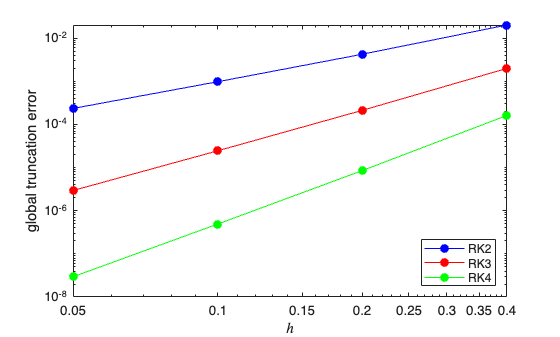

% Plot errors
hold on
hplot(1) = loglog(hvals, error_rk2, 'b-o', MarkerFaceColor='b');
hplot(2) = loglog(hvals, error_rk3, 'r-o', MarkerFaceColor='r');
hplot(3) = loglog(hvals, error_rk4, 'g-o', MarkerFaceColor='g');
hold off
xlabel('$h$', Interpreter='latex')
ylabel('global truncation error')
legend(hplot, {'RK2', 'RK3', 'RK4'}, Location='SouthEast')

% Estimate errors
if true % to keep printed lines together
fprintf('RK2: n = %0.2f', (log(error_rk2(1)) - log(error_rk2(end))) / (log(hvals(1)) - log(hvals(end))))
fprintf('RK3: n = %0.2f', (log(error_rk3(1)) - log(error_rk3(end))) / (log(hvals(1)) - log(hvals(end))))
fprintf('RK4: n = %0.2f', (log(error_rk4(1)) - log(error_rk4(end))) / (log(hvals(1)) - log(hvals(end))))
end

RK2: n = 2.14

RK3: n = 3.13

RK4: n = 4.14

## Exercise 2.11

function [t, y] = rk23(f, tspan, y0, atol, rtol)

m = length(y0);
t = zeros(100000, 1);
y = zeros(100000, m);
t(1) = tspan(1);
y(1,:) = y0;

h = 0.8 * rtol ^ (1/3);
n = 1;
nfail = 0;
while t(n) < tspan(2)

    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + 1/2 * h, y(n,:) + 1/2 * h * k1);
    k3 = f(t(n) + h, y(n,:) + h * (-k1 + k2)); 
    y3 = y(n,:) + h / 6 * (k1 + 4 * k2 + k3); 
    y2 = y(n,:) + h * k2;

    delta = norm(y3 - y2);
    tol = atol + rtol * min(abs(y3));
    if delta < tol
        y(n+1,:) = y3;
        t(n+1) = t(n) + h;
        n = n + 1;
    else
        nfail = nfail + 1;
    end

    r = max(0.1, 0.8 * (tol / delta) ^ (1/3));
    h = min(r * h, tspan(2) - t(n));
end

t(n+1:end) = [];
y(n+1:end,:) = [];

fprintf('Number of successful steps:     %i\n', n - 1)
fprintf('Number of failed steps:         %i\n', nfail)
fprintf('Number of function evaluations: %i\n', (n - 1 + nfail) * 3)

end

% Solve IVP
atol = 1e-6;
rtol = 1e-3;
[t, y] = rk23(f, tspan, y0, atol, rtol);

Number of successful steps:     24
Number of failed steps:         2
Number of function evaluations: 78


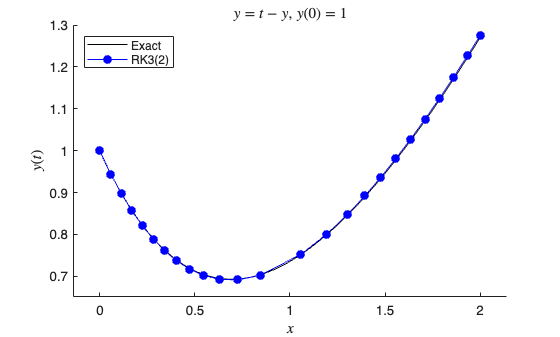

% Plot solution
clf
hold on
plot(texact, yexact, 'k')
plot(t, y, 'b-o', MarkerFaceColor='b')
hold off
xlabel('$x$', Interpreter='latex')
ylabel('$y(t)$', Interpreter='latex')
title('$y = t - y$, $y(0) = 1$', Interpreter='latex')
legend('Exact', 'RK3(2)', Location='NorthWest')
axis padded